# Live Script PageRank - mathwork200.mat

### Caricamento file .mat

load mathwork200.mat;

### Elaborazione

Di seguito si utilizza la funzione pagerank tramite il function file pagerank.mlx. Con i risultati forniti dalla funzione, vengono generati i grafici richiesti:  un grafico che visualizza la struttura di G, il grafo associato, i primi 15 risultati in ordine decrescente con i corrispondenti outdegree e indegree, un grafico a barre del PageRank ed il sottografo costituito dai nodi con rank maggiore della media dei rank. 

#### Struttura di G

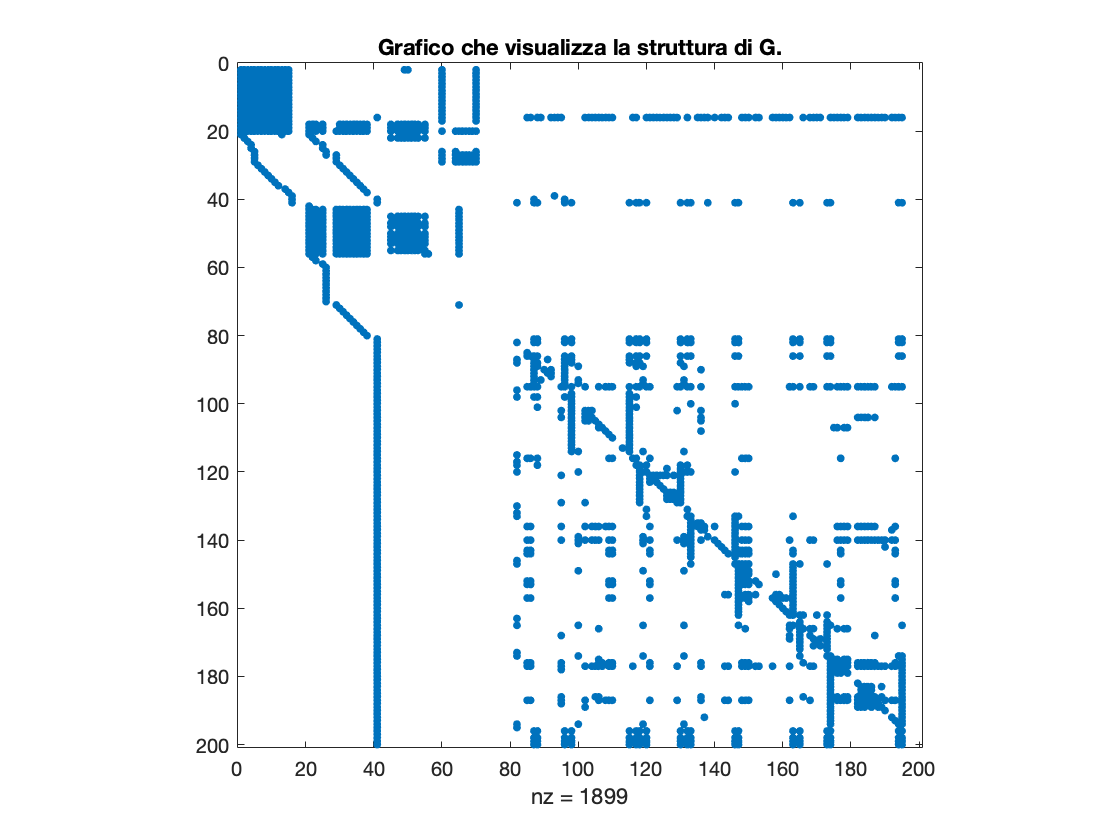

figure('Name','Struttura di G', 'NumberTitle','off');
spy(G);
title('Grafico che visualizza la struttura di G.');

#### Grafo di G

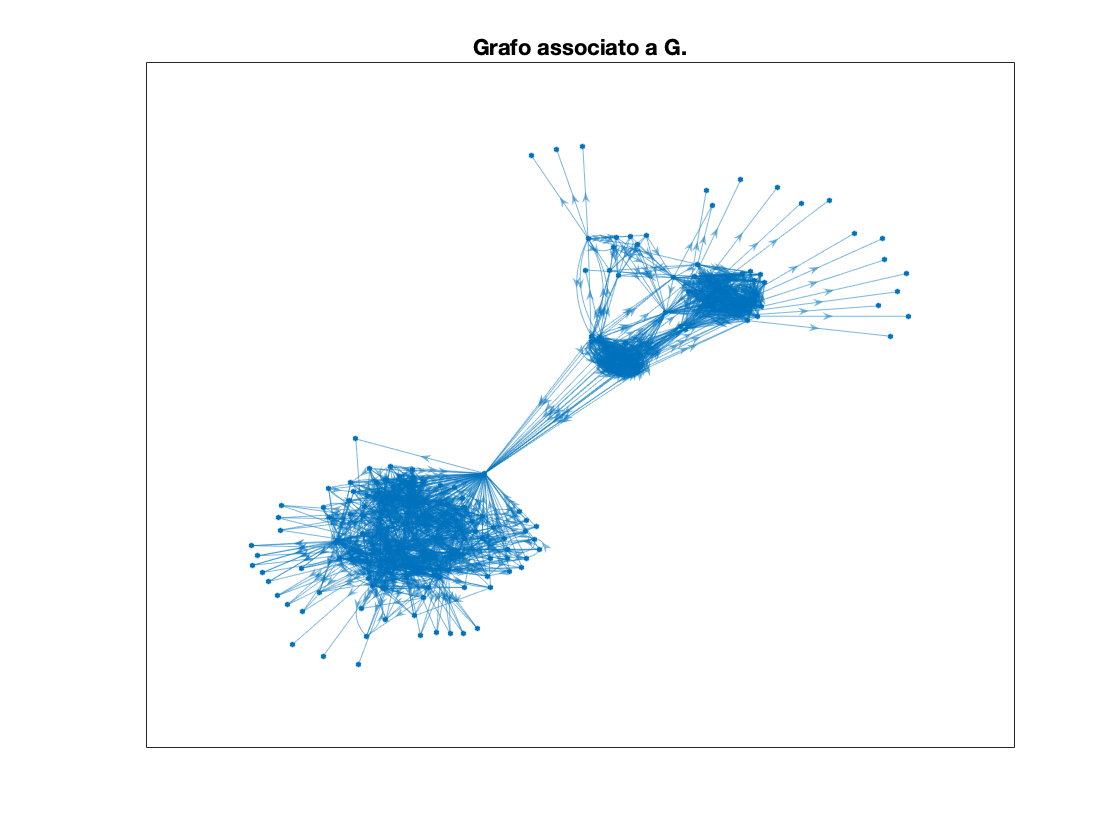

figure('Name','Grafo di G', 'NumberTitle','off');
gs = digraph(G', 'omitselfloops');
p = plot(gs);
layout(p,'force');
title('Grafo associato a G.');

#### Calcolo PageRank

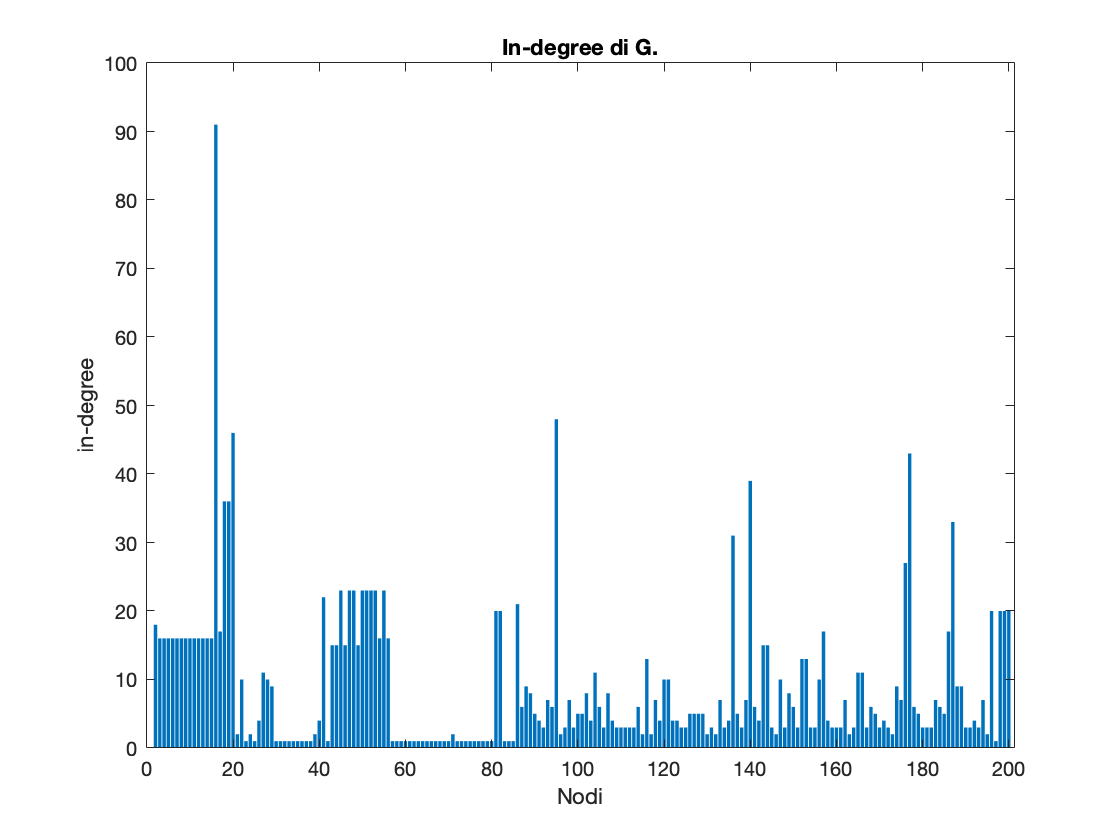

[R, outdegree, indegree] = pagerank(G);
figure('Name','Bar Plot degli in-degree di G', 'NumberTitle','off');
bar(indegree);
xlabel("Nodi");
ylabel("in-degree");
title('In-degree di G.');

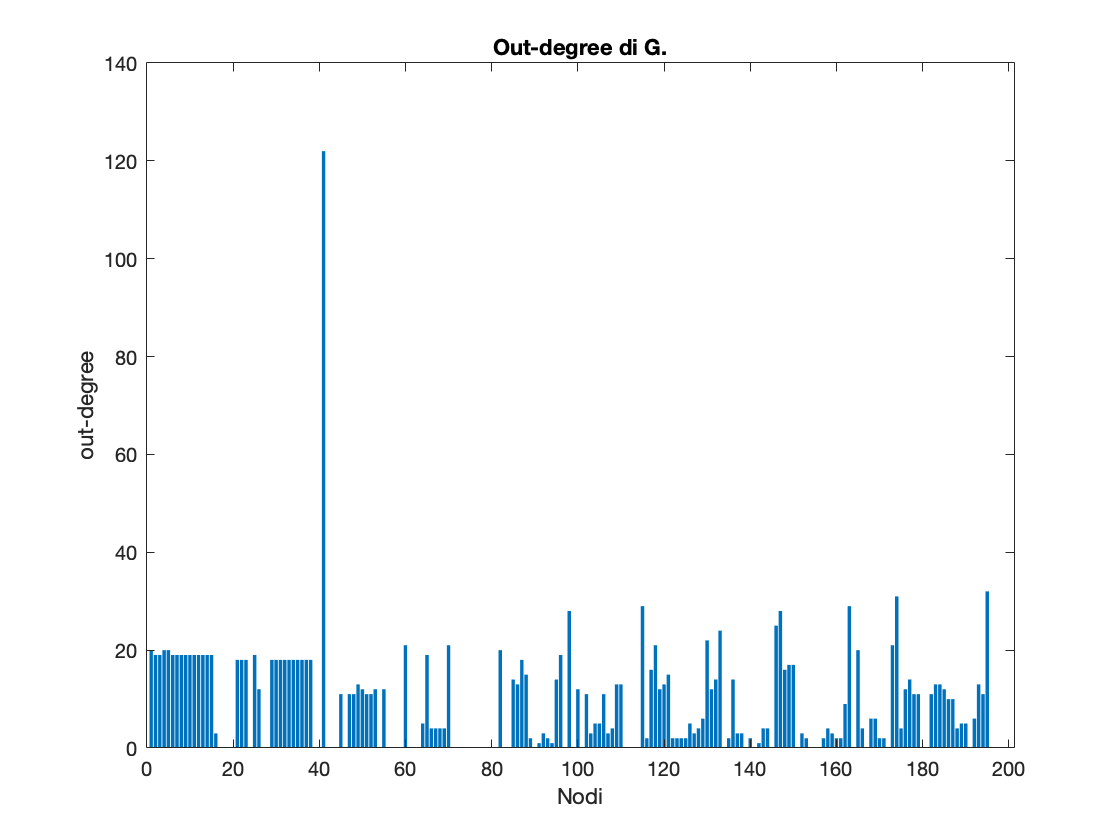

figure('Name','Bar Plot degli out-degree di G', 'NumberTitle','off');
bar(outdegree);
xlabel("Nodi");
ylabel("out-degree");
title('Out-degree di G.');

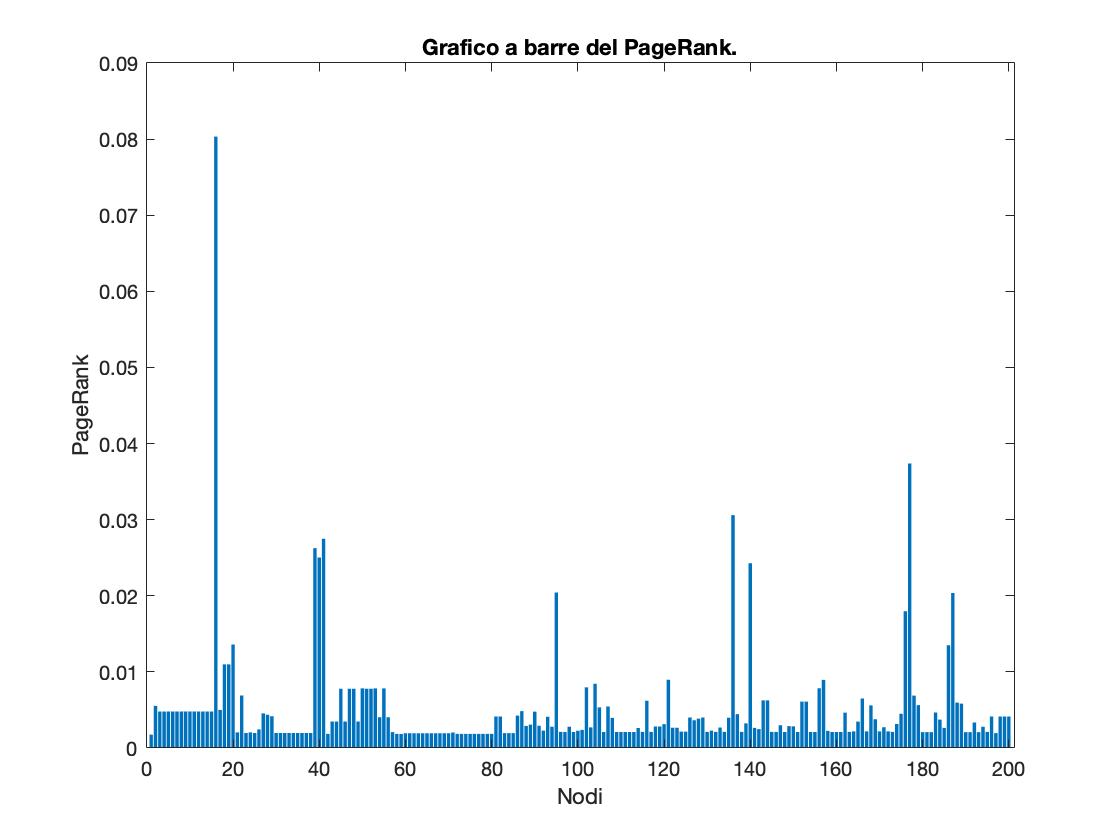

figure('Name','Grafico del PageRank di G', 'NumberTitle','off');
bar(R);
xlabel("Nodi");
ylabel("PageRank");
title('Grafico a barre del PageRank.');

#### Tabella 15 pagine più importanti

outdegree = outdegree';
T = table(U, indegree, outdegree, R);
T = sortrows(T, 'R', 'descend');
T = head(T,15);
disp(T);

                            U                            indegree    outdegree       R    
    _________________________________________________    ________    _________    ________

    'http://schema.org'                                     91            3       0.080319
    'http://schema.org/CreativeWork'                        43           14       0.037379
    'http://schema.org/Offer'                               31           14       0.030589
    'http://blog.schema.org'                                22          122       0.027485
    'http://schema.org/docs/about.html'                      2            0       0.026261
    'http://github.com/schemaorg/schemaorg'                  4            0       0.025032
    'http://schema.org/image'                               39            2       0.024282
    'http://schema.org/Person'              

#### Sottografo di G

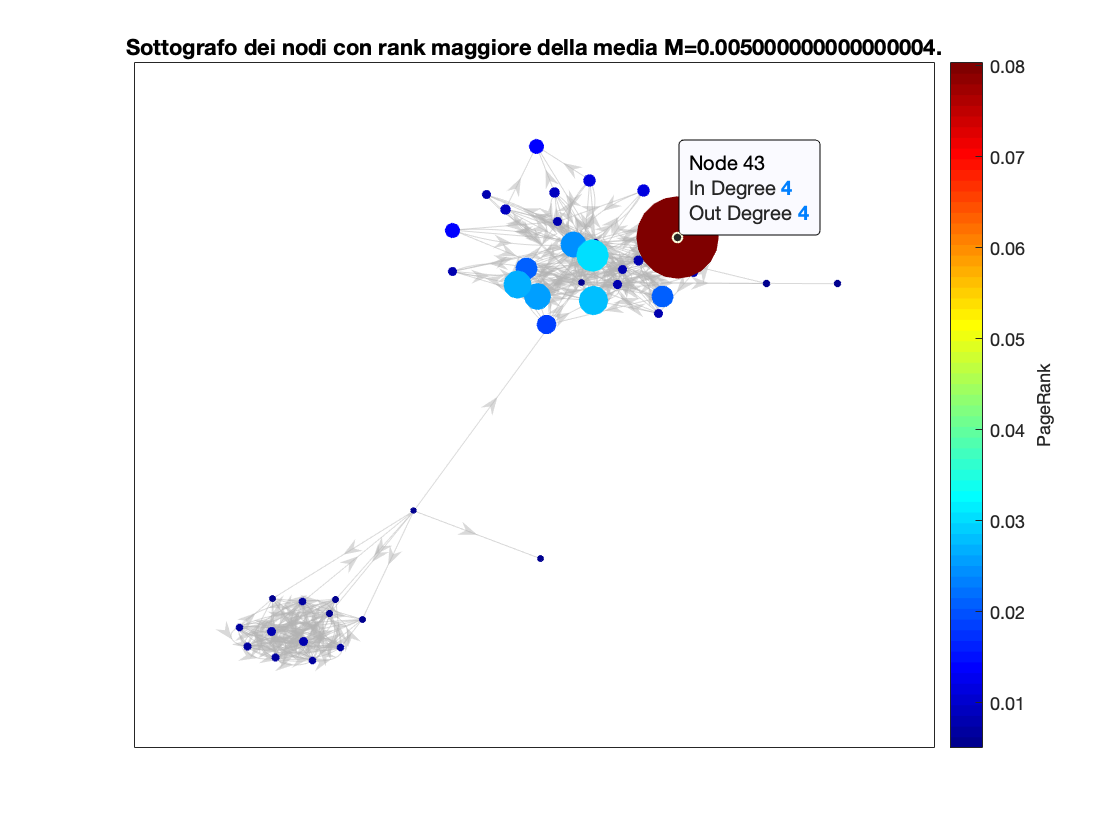

%%%% Plot del sottografo %%%%%

M = mean(R); % Calcolo media.
rk_s = sort(R(R>M)); % Vettore dei rank ordinati.
g_media = subgraph(gs, R>M); % Sottografo dei nodi con rank maggiori della media.


% Plot effettivo del sottografo
figure('Name','Sottografo di G', 'NumberTitle','off');
sizes = rk_s*500;
gr = [.7 .7 .7];
p=plot(g_media,'NodeLabel',{},'MarkerSize',sizes,'NodeCData',rk_s,'EdgeColor',gr);
colormap jet; % Impostazione colormap per bar laterale.
layout(p,'force'); % Disposizione nodi
ylabel(colorbar, 'PageRank'); % Aggiunta label alla bar laterale.

% Visualizzazione rank nella label del nodo (vedi funzione GraphCursorCallback.m).
g_media.Nodes.PageRank = rk_s; % Impostiamo la voce PageRank nella label.
hdt = datacursormode;
hdt.UpdateFcn=@(obj, event_obj)GraphCursorCallback(obj,event_obj,g_media.Nodes);

% Aggiunta titolo al grafico.
title(['Sottografo dei nodi con rank maggiore della media M=' num2str(M,16) '.']);